**Daniel Park | 11/17/20**

# **QEA Project 1: Faces Project**

## **1. Summary**

This report will detail my process of implementing a face recognition system that will automatically load an image, or manually select an image, and then will find an image of the same person from the image dataset. In addition to a working system, this report would also address how the introduction of a face mask obstructing some vital facial parts will affect the system in place and how we would fix our system in accordance to that. The introduction will take about the implications of the project and potential bias of the algorithm, the methods will go into detail about how the system was made, the detailed findings will discuss my completed system and the corresponding graphs for verification and validation information, the recommendation section goes over key findings of my model and areas for future investigation, and finally the references section with all the sources reference in this report paper.

## **2. Introduction**

Facial Recognition Systems is a relatively modern technology that is capable of matching a human face from a digital image or video frame against a database of faces. This technology is mostly utilized to authenticate users through identification services while also being deployed in advanced human-computer interaction, video survelliance, and more recently, smartphone and robotics identification software. Over the past couple of decades, people have discovered numerous ways of deploying a facial recognition software such using different types of machine learning techniques or using a convolutional neural network (CNN for short) to recognize faces, but the way this report will explore a simpler approach founded by Matthew A. Turk and Alex P. Pentland in 1991 is called the "eigenvector-based recongition system" and have the software automatically or manually load a specific image within the dataset and find an image of the same person from the same data-set. [1]

Although deploying a facial match recognition system is straightforward enough, possible ethical issues or obstructions may surface especially during this time of mass pandemic. During COVID-19, the wearing of facemasks has become an essential part of public life, as has the enforcement of mask-wearing in stores and other public places. This type of system that identifies faces may be difficult with the introduction of a mask on the face. Since a large part of the face would be covered with a mask, the system would definitely be more inaccurate in matching face images with an introduction of a mask. And since this algorithm would be servicing a large and diverse population, not just a specific demographic, reducing bias in training data will be necessary to prevent accuracy issues once deployed. 

So in light of these possible controversies, this report will answer the question **"****Can we make an algorithm that takes in a dataset of people and using eigenfaces, detect a image from within the dataset that matches the face?****"** with its corresponding sub-question, **"Is it possible to take in account the facemasks people wear now that will now obstruct a large majority of the face when matching faces? And if so, how can we do it?"**

## **3. Methods**

*Having introduced the reader to terminology and ideas, this section should lay out the approaches you are using, both in terms of the chosen algorithm and the analysis you are doing with it. Use equations and dene all variables. (Go into detail later)*

### 3.1 Preparing the Dataset

In order to answer our question, we have to find a dataset that has a large number of individuals with a variety of images attached to each individual with a corresponding masked and unmasked image for each image. 

The visual below will help explain things more clearly:

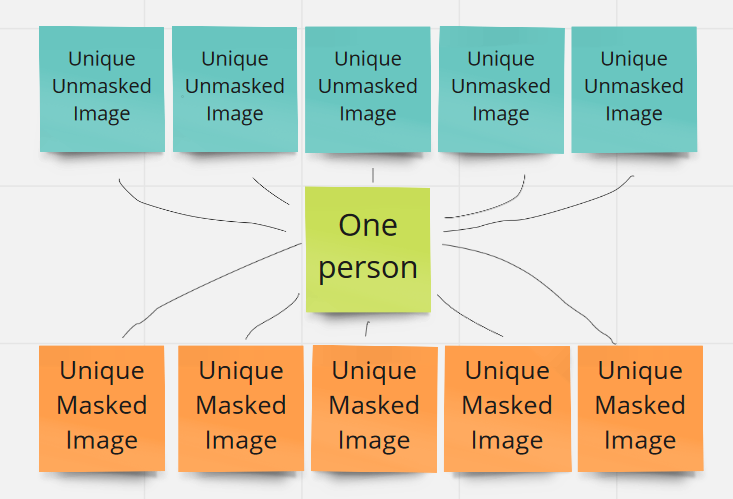

Unforunately, there are no datasets out there that will help us directly accomplish that, so we must take an existing database of faces and make a copy of each of those images with a mask on their face. The database that we will use is the the ORL (Our Database of Faces) Batabase from AT&T Laboratories in Cambridge. [2]

The ORL Database contains a set of face images taken between April 1992 and April 1994 at the laboratory for the sole purpose of a face recognition project carried out with the Speech, Vision, and Robot Group of the Cambridge University Engineering Department. The dataset has ten different images of each of 40 distinct subjects. For some subjects, the images were taken at different times, varying the lighting, facial  expressions (open / closed eyes, smiling / not smiling) and facial details (glasses / no glasses). All the images were taken against a dark homogeneous background with the subjects in an upright, frontal position (with tolerance for some side movement).

This was a perfect dataset for use because the images were already in grayscale and each had the same resolution and dimension of a 92 x 112 pixel image. So using Adobe Photoshop, I saved the dataset to my computer and pasted in a grayscaled mask covering the nose and mouth of each face. Since the algorithm won't be affected by less subjects since we are not removing the ten images for each face, it will save time working with only ten subjects rather than pasting masks on Adobe Photoshop for longer than was necessary. 

### 3.2 Loading the Dataset

Now that we have both the mask dataset and no mask dataset, we can load our dataset

%% Description
% Loads the dataset in preparation for face recognition

%% Variables
loadedImage = [];
numImage = [];

%% Dataset Loading Function
if(isempty(loadedImage)) 
    allImages = zeros(112*92,... % Pixels of each image
        40); % Number of folders representing a single person
    cd(strcat('training_set')); 
    for i=1:40 
        cd(strcat('s',num2str(i))); 
        for j=1:10 
            imageContainer = imread(strcat(num2str(j),'.pgm')); 
            allImages(:,(i-1)*10+j)... % get all images from each folder
                = reshape(imageContainer,size(imageContainer,1)... 
                *size(imageContainer,2),1); % reshape images into arrays for analysis
        end
        disp('Loading Database');
        cd .. % changes folder directory back to load other faces
    end
    numImage = uint8(allImages); % changes all the images within the database to 8-bit images
end

Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database
Loading Database


loadedImage = ""; % Needs to return to empty next time image needs to be loaded
output_image = numImage; 

### 3.3 Face Analysis Using Eigenvectors

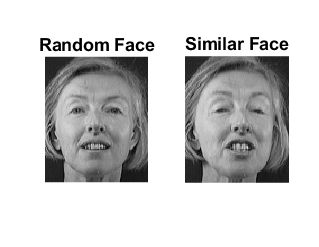

%% Description
% When file is run, it will load random image and find an image closest to
% the loaded image

%% Load random image and display it
loadedImage = output_image;
randomIndex = round(400*rand(1,1));          
randomImage = loadedImage(:,randomIndex);
imshow(reshape(randomImage,112,92));

%% Get variables for analysis

% Store all images minus chosen image into an array
remainingImages = loadedImage(:,[1:randomIndex - 1 randomIndex + 1:end]);

% Blank image for resetting tracking images
blankImage = uint8(ones(1,size(remainingImages,2)));

% Find mean of remaining images and remove them from chosen image
meanValue = uint8(mean(remainingImages,2));                
meanRemovedImage = remainingImages - uint8(single(meanValue)*single(blankImage));

% Finding the eigenvector of image
A = single(meanRemovedImage)'*single(meanRemovedImage);
[V,D] = eig(A);
V = single(meanRemovedImage)*V;

% Create structures for each individual image
imageSignature = 20; % Play around with this   
V=V(:,end:-1:end-(imageSignature-1));          
allImageSignatures=zeros(size(remainingImages,2),imageSignature);

% Multiply eigenvectors and store with the image signatures
for i=1:size(remainingImages,2)
    allImageSignatures(i,:) = single(meanRemovedImage(:,i))'*V;  
end

%% Find closest possible face

% Show random image onto a popup plot
subplot(121);
imshow(reshape(randomImage,112,92));
title('Random Face');

% Calculate closest possible face
subplot(122);
p = randomImage-meanValue;
s = single(p)'*V;
B=[]; % empty array that stores search image signature

for i=1:size(remainingImages,2)
    B = [B,norm(allImageSignatures(i,:)-s,2)];
    if(rem(i,20) == 0),imshow(reshape(remainingImages(:,i),112,92)),end;
    drawnow;
end

% Show calculated closest image
[a,i] = min(B);
plot(122);
imshow(reshape(remainingImages(:,i),112,92));
title('Similar Face');

## **4. Detailed Findings**

*This section should contain your main results and consequences of your work which you have quantied.This section should contain some clear, informative, labeled, and captioned plots and images that demonstrate your findings. Quantitative results should be clearly connected to the context of the investigation. Why are your findings meaningful? Reflect on the downsides of the technology and the people it could hurt, and suggest some strategies for improvement*

## **5. Recommendations**

*Summarize the key ndings of the report, situate them in the greater context,and identify areas for future investigation. This section should be concise—they details go in the previoussection*

In summary, trying to use eigenvectors to match two images together where one image has a mask and the other doesn't have a mask is very ineffective. Although the system was able to get some of the matching images correct, it is obvious to see that most of images that were analyzed and compared with were incorrect. If we were to improve our system, we would most likely only rely on upper half ot the face (eyes and hair) to match images instead of using the masks as well. And although that would still cause inaccuracies in our model, it would also increase the accuracy of matching faces with their masked correspondents. But overall, we can conclude that face masks make facial recognition very difficult and we would most likely see a unique approach to facial recognition if we were to accurately match faces with face coverings. 

## **6. References**

*Provide full citations for sources referenced in the paper. Format doesn’t matter here as long as you providesucient information about each of your sources.*

[1] Face Recognition Using Eigenfaces 1991 Report: [http://www.mit.edu/~9.54/fall14/Classes/class10/Turk%20Pentland%20Eigenfaces.pdf](http://www.mit.edu/~9.54/fall14/Classes/class10/Turk%20Pentland%20Eigenfaces.pdf)

[2] ORL Training Dataset 40 Images: [https://www.kaggle.com/kasikrit/att-database-of-faces](https://www.kaggle.com/kasikrit/att-database-of-faces)

[3] Context of the ORL Training Dataset: [http://cam-orl.co.uk/facedatabase.html](http://cam-orl.co.uk/facedatabase.html)